# Applying Optical Flow

In the "Applying Optical Flow" video, you saw how to use optical flow to isolate moving objects in a video of a busy street.

In this reading, you will create a motion detector using optical flow and image processing, then apply it to calculate the speed of moving objects.

You will:

- Apply optical flow to a portion of the pedestrian video

- Visualize optical flow vectors

- Create a motion color intensity map

- Filter optical flow vectors by magnitude

- Use image processing to isolate moving objects

- Use `regionprops` to calculate object speed

## Experiment with Optical Flow in Sample Frame

When applying optical flow, it's a good idea to start with just a few frames to get a feel for the overall motion. In the code below, we intentionally selected a frame with a fast-moving bicycle.

### Create Video Reader Object

Use the same pedestrian tracking video included with MATLAB that you used previously:

vid = VideoReader("pedtracking.mp4");         

### Create Optical Flow Solver

Use the Farneback method for solving the optical flow equation to estimate x and y velocities:

of = opticalFlowFarneback;

### Plot Optical Flow Vectors

Select a frame to apply the optical flow solver to. The frame with the bicycle was found via inspection in the Video Viewer app. 

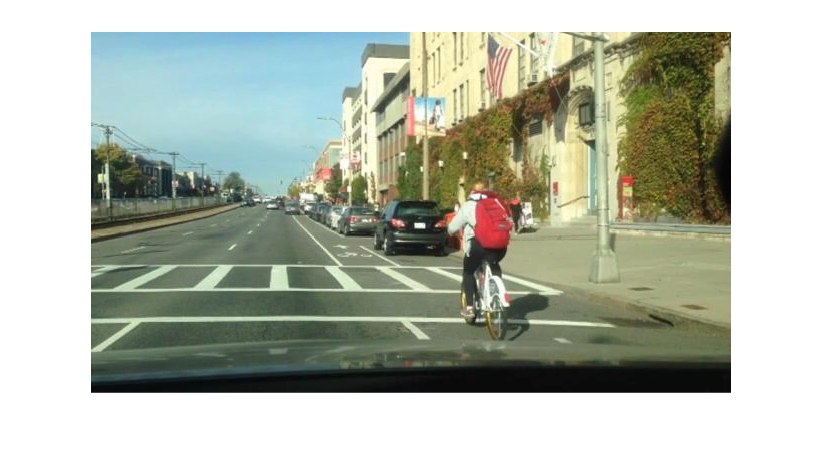

testFrameIdx = 349;
testFrame = read(vid,testFrameIdx);
imshow(testFrame)

Initialize the optical flow solver using the test frame. Remember that the first time the optical flow solver is called, it compares the image to an all-black background. Thus, ignore the output the first time we use the `estimateFlow` function.

estimateFlow(of,im2gray(testFrame));

Calculate the optical flow based on differences between the initial test frame and the subsequent frame to estimate a velocity vector for every pixel.

testFrame = read(vid,testFrameIdx + 1);
testFlow = estimateFlow(of,im2gray(testFrame))

testFlow =   opticalFlow with properties:

             Vx: [360×640 single]
             Vy: [360×640 single]
    Orientation: [360×640 single]
      Magnitude: [360×640 single]


The flow variable is of data type `opticalFlow` and contains the following information for each pixel:

    $V_x$ - the velocity of each pixel's optical flow in the *x* direction 

    $V_y$ - the velocity of each pixel's optical flow in the y direction

    $\textrm{Orientation}$ - the phase angle of each pixel's optical flow in radians

    $\textrm{Magnitude}$ - the magnitude of each pixel's optical flow

Plot the optical flow vectors. The `"DecimationFactor"` and `"ScaleFactor"` options you need will depend on the video resolution and the amount of motion.

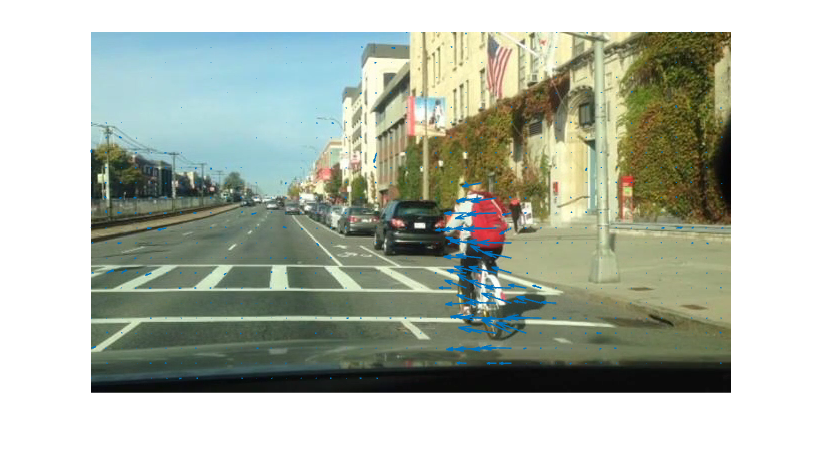

imshow(testFrame)
hold on
plot(testFlow,"DecimationFactor",[15 15],"ScaleFactor",7)
hold off

### Creating Motion Color Intensity Maps

For many applications, the magnitude of motion (or speed) is more important than motion in a given direction. Often, you will need to filter out noise or focus only on flow vectors with a magnitude above a certain threshold.

In the video, you saw how to use flow magnitude histograms to determine an appropriate threshold to isolate moving objects. Another visually intuitive way to view flow magnitude and choose a threshold is to create a color intensity map. Faster-moving objects are yellow, and stationary objects are dark blue.

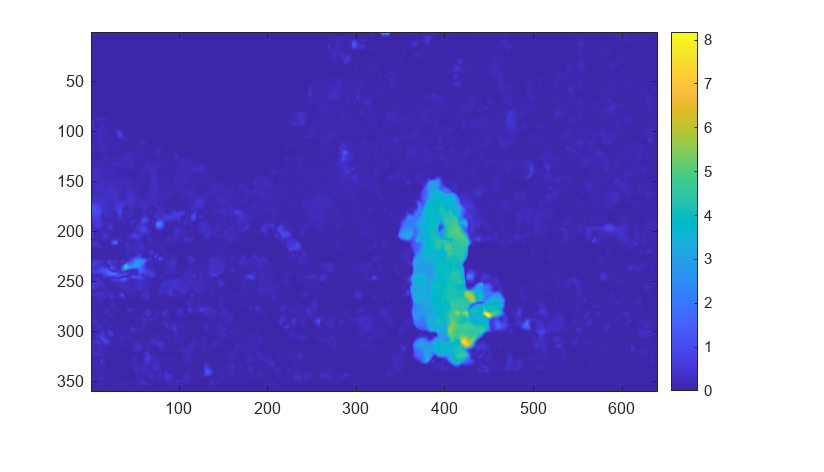

imagesc(testFlow.Magnitude)
colorbar

### Thresholding Optical Flow Vectors

Using the above color intensity map as a guide, set a magnitude threshold, `magThresh`, to create and visualize a new optical flow object that includes only values above the threshold. Feel free to experiment with different thresholds and examine their effects.

Note that because each 2-dimensional video frame portrays a 3-dimensional scene, objects further from the camera will appear to be moving slower than objects closer to the camera. 

% Create threshold
magThresh = 1;
threshFlow = testFlow.Magnitude >= magThresh;

Assign all $v_x$ and $v_y$ values below the threshold to zero.

VxThresh = testFlow.Vx;
VxThresh(~threshFlow) = 0;

VyThresh = testFlow.Vy;
VyThresh(~threshFlow) = 0;

Create a new, thresholded optical flow object.

magThreshFlow = opticalFlow(VxThresh,VyThresh);

Plot thresholded optical flow vectors

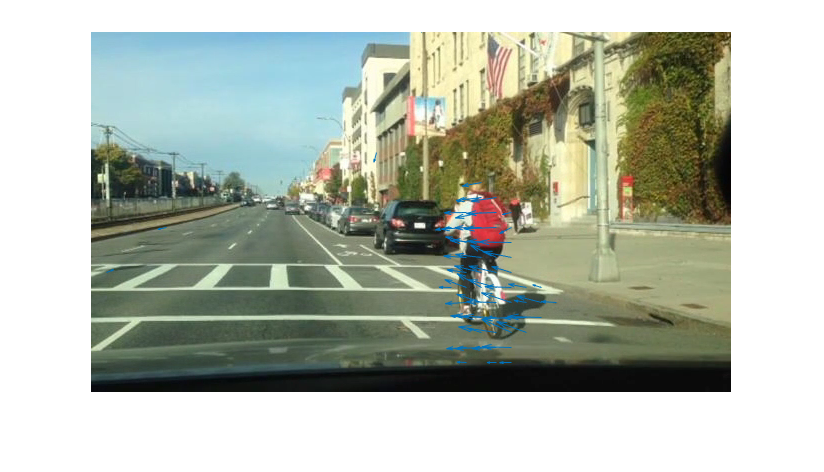

imshow(testFrame)
hold on
plot(magThreshFlow,"DecimationFactor",[15 15],"ScaleFactor",7)
hold off

## Calculate Object Speed

Now that you have had a chance to experiment with displaying optical flow, in the following code, you will create a labeled video showing only objects with relatively high average flow magnitude, or speed.

### Initialize Optical Flow

% The file to write the new video to
vidOut = VideoWriter("pedtracking_avgMag");

startFrame = 96;
endFrame = 565;

% Baseline frame
of = opticalFlowFarneback;
frame = read(vid,startFrame);
estimateFlow(of,im2gray(frame));

% Compare next frame to baseline to calculate optical flow
frame = read(vid,startFrame + 1);
flow = estimateFlow(of,im2gray(frame)); 

### Detect Moving Objects

In the "Applying Optical Flow" video, you saw how to create a mask including only parts of the image with a flow magnitude above 0.5:

magThresh = 0.5;
mask = (flow.Magnitude > magThresh);

Then, you saw how to use image processing to remove unwanted noise from the image. Specifically:

Performing morphological opening to remove noise from the mask:

se = strel("disk",3,0);
mask = imopen(mask,se);

And keeping only larger regions of the mask:

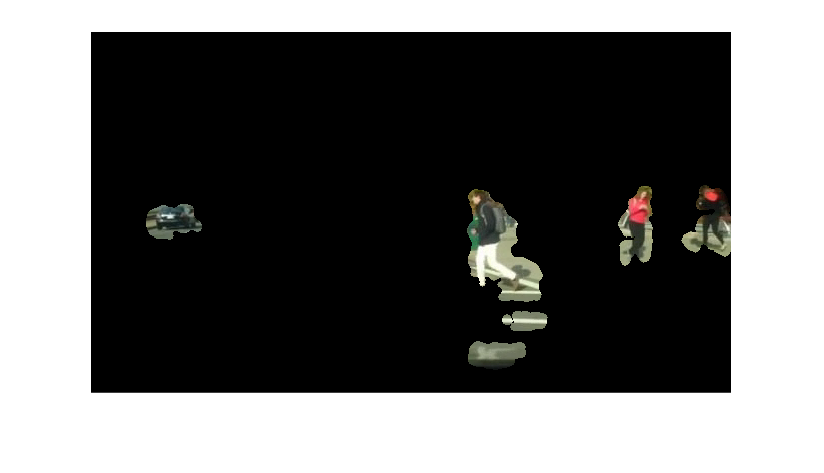

mask = bwareafilt(mask,[500, Inf]);

maskedFrame = frame;
% Apply mask to all color spaces
maskedFrame(repmat(~mask,[1 1 3])) = 0;
imshow(maskedFrame)

To this process, we will add a step: calculating the speed per moving object.

### Calculate Object Speed

You have already thresholded optical flow vectors by magnitude. However, we are often less interested in individual flow vectors than in an object's overall motion.

You can calculate the speed for each object using `regionprops`. To do this, input the mask and the optical flow magnitude as inputs to the `regionprops` function. The function can then return properties like `"MeanIntensity"`. For example, for each region in `mask`, the `"MeanIntensity"` is calculated for the corresponding locations in `"flow.Magnitude"`.   

The bounding box is also returned. The bounding box is added to the frame and labeled with the mean intensity.

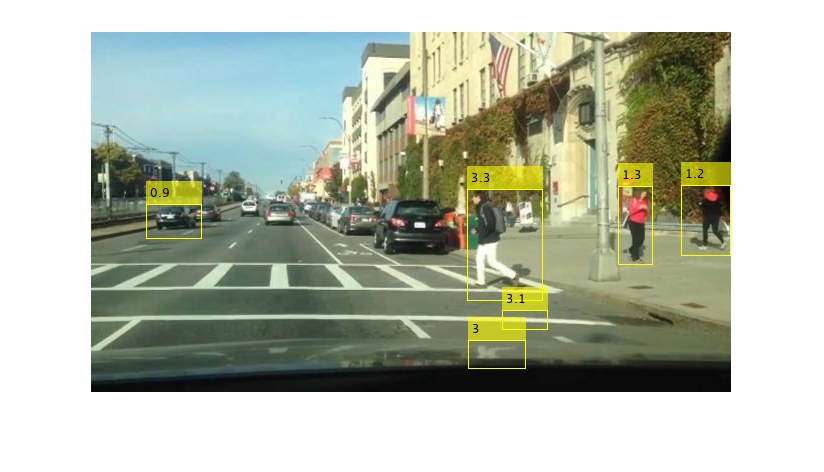

movObjs = regionprops("table",mask,flow.Magnitude,["MeanIntensity","BoundingBox"]);

if ~isempty(movObjs)
    labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity,1)));
end
imshow(labelFrame)

Once you are happy with your results, you can write this as the first frame in your new labeled video.

open(vidOut)
writeVideo(vidOut, labelFrame)

### Create Labeled Video

Now that you are confident in your algorithm repeat the above steps for every frame in the video (starting with the next frame).

This may take a few minutes.

for ii = startFrame+2:endFrame
    frame = read(vid,ii);
    flow = estimateFlow(of,im2gray(frame));
    
    % Create the mask for pixels with high optical flow magnitude values
    mask = flow.Magnitude > magThresh;

    % Remove unwanted signal from the mask
    se = strel("disk",3,0);
    mask = imopen(mask,se);
    mask = bwareafilt(mask,[500, Inf]);
    
    % Create magnitude labels
    movObjs = regionprops("table",mask,flow.Magnitude,"MeanIntensity","BoundingBox");
    
    % Check that there has been a detection
    if ~isempty(movObjs)    
        labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity,1)));
    end

    % Write new masked frame to video reader
    writeVideo(vidOut,labelFrame)
end

close(vidOut)

You're ready to play the resulting video. How well did your detection identify fast-moving objects? Were there any false detections? If so, why do you think that happened?

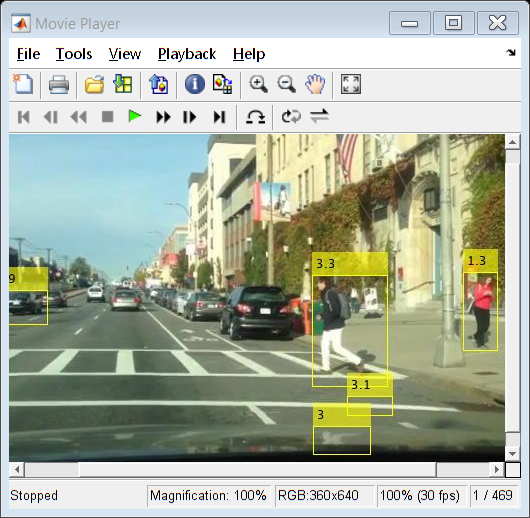

implay("pedtracking_avgMag.avi")

*Copyright 2022 The MathWorks, Inc.*